# Simulate a Universal Robots UR5 Using MATLAB and Gazebo for Glue Dispensing on a Windshield

This example shows how to design and validate real-life application workflows for a robotic manipulators like the UR5e cobot from [Universal Robots](https://www.universal-robots.com/), using Interactive Rigid Body Tree and Gazebo® physics simulator, Robotics System Toolbox™, and ROS Toolbox.

### Overview

This example demonstrates motion planning and execution for a glue dispensing application using a cobot. A task space based trajectory algorithm is demonstrated in this example using Robotics System Toolbox features. The trajectory planning ensures that we get approximately constant TCP (Tool Center Point) linear velocity for uniform glue dispensing on the windshield object (considered as a reference object for the demonstration).

In this example, first we will use the rigid body tree models to plan and simulate the trajectory in MATLAB® and later we will use the Gazebo physics simulator and [urROSNode](docid:urseries_ref#mw_18467442-5c48-439a-8886-8318ba5d00e1) object to validate the cobot control and motion across the precalculated task space trajectory. All the necessary files required to setup Gazebo are included in the support package. Refer to [Install ROS Packages and Dependencies for ROS](docid:urseries_ug#mw_313af52d-db69-4e68-809e-09dfa1fb9273) for more details.

Clear all output in the live script by right-clicking anywhere in the live script and then clicking ‘Clear All Output’ or navigate to VIEW > Clear all Output.

**Note: Execute the script section by section as mentioned in this example.**

**Required Products**

- Robotics System Toolbox

- Robotics System Toolbox Support Package for Universal Robots UR Series Manipulators

- ROS Toolbox

## **Motion Planning and Rigid Body Tree Simulation**

### **Load Robot Model **

This example uses the Universal Robot cobot model UR5, a 6 degree-of-freedom robot manipulator. The [`loadrobot`](https://www.mathworks.com/help/robotics/ref/loadrobot.html) generates a [`rigidBodyTree`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.html) model from a description stored in a Unified Robot Description Format (URDF) file. 

Load rigid body tree model of Universal Robot UR5.

ur5_RBT = loadrobot("universalUR5");
ur5_RBT.DataFormat = 'row';

### **Add a Dummy Glue Dispenser Tool at the End-Effector Body**

For the glue dispensing application, add a dummy glue dispenser at the end-effector of the cobot using [`addBody`](https://www.mathworks.com/help/robotics/ref/rigidbodytree.addbody.html#d123e52486). The visuals can be added by [`addVisuals`](https://www.mathworks.com/help/robotics/ref/rigidbody.addvisual.html) using the STL file. [interactiveRigidBodyTree](https://www.mathworks.com/help/robotics/ref/interactiverigidbodytree.html) functionalities are used in this example to set the orientation of the end-effector using marker body.

Define the inline function for rotations around x-axis to use in further code sections.

rotationX = @(t) [1 0 0; 0 cosd(t) -sind(t) ; 0 sind(t) cosd(t)] ;

Add dispenser body to the 'tool0' (default end-effector body).

glueDispenserBody = rigidBody('dispenser');
addVisual(glueDispenserBody,"Mesh",'glueDispenserMesh.STL')
glueDispenserBodyJoint = rigidBodyJoint('glueDispenserBodyJoint','fixed');
glueDispenserBody.Joint = glueDispenserBodyJoint;
transfForglueDispenserBody = rotm2tform(rotationX(-90));
setFixedTransform(glueDispenserBody.Joint, transfForglueDispenserBody)
curEndEffectorBodyName = ur5_RBT.BodyNames{10};
addBody(ur5_RBT,glueDispenserBody,curEndEffectorBodyName)

Add one more fixed-body at the tip of the dispenser gun to compute the desired inverse transform in further sections.

transfForNewEndEffectorBody = rotm2tform(rotationX(180));
transfForNewEndEffectorBody(:,4) = [0.04; -0.195; 0; 1];
newEndEffectorBody = rigidBody('dispenserEdge');
setFixedTransform(newEndEffectorBody.Joint, transfForNewEndEffectorBody);
glueDispenserBodyName = ur5_RBT.BodyNames{11};
addBody(ur5_RBT,newEndEffectorBody,glueDispenserBodyName);

### **Visualize the Robot Model**

Create an interactive rigid body tree object and associated figure.

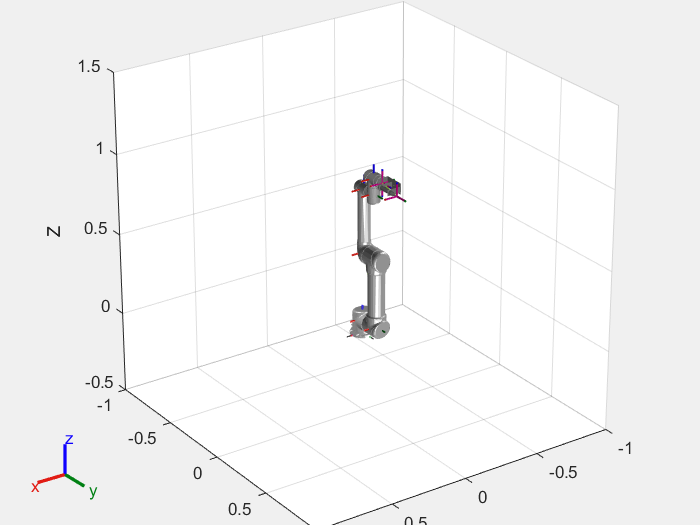

% Close the previous figure window before running the script again
close(findobj('type','figure','name','Interactive Visualization'));

% Visualize the interactive rigid body tree at the home position ('q_home')
ur5_iRBT = interactiveRigidBodyTree(ur5_RBT);
q_home = [0 -90 0 -90 0 0]'*pi/180;
rotate3d off;
view(145,25)
lightangle(20,-160)
axis([-1 1 -1 1 -0.5 1])
hold on
zlim([-0.5 1.5])
ur5_iRBT.ShowMarker = false;
ur5_iRBT.Configuration = q_home;

### **Load Windshield STL Model for Glue Dispensing Application in the Same Rigid Body Tree Environment**

This section loads the windshield STL object with the Rigid Body Tree robot world. Attach the 'ButtonDownFcn' callback function to the patch object of the windshield body to enable waypoint selection from the object surface using mouse button click. 

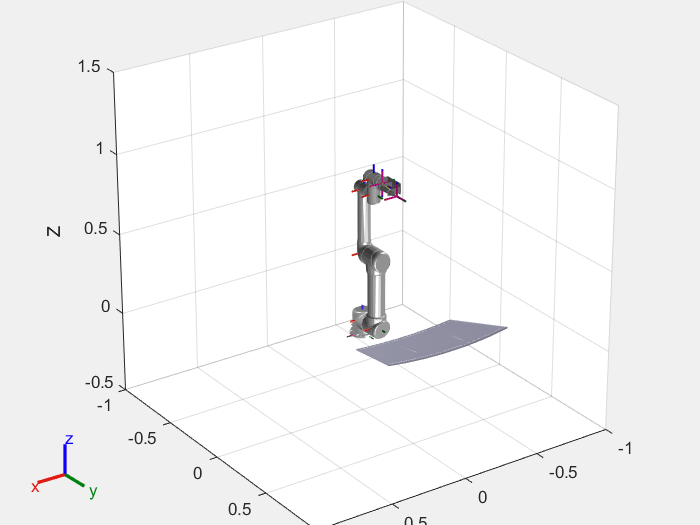

% Load STL object and get patch object
windshield = stlread('windshieldv3.stl');
orintationOfWindshield = 55; % In degree
locationOfWindshield = [0 0.4 0.15]; % With respect to global frame of the world [x y z]
windshieldPatch = patch(gca,'Faces',windshield.ConnectivityList,'Vertices',(windshield.Points*rotationX(orintationOfWindshield)) ...
    + locationOfWindshield,'FaceColor',[0.8 0.8 0.9],'LineStyle','none');

% Attaching the ButtonDownFcn callback
set(windshieldPatch,'ButtonDownFcn',{@exampleHelperSelectWaypoints});

### Select Desired Waypoints on Windshield Body Using Mouse Button Callback

Select waypoints on the object before executing this section. Use mouse button click to select the desired waypoints. You can notice that after each successful selection, a green marker point will appear on the windshield body.

**Note: If you want to consider the default waypoints for coming sections, then you can run this section without selecting any waypoints.**

### **Get the Selected Waypoints Data**

Get the coordinates of the selected waypoints for the motion planning. If no waypoints are selected, the model uses the default waypoints as mentioned in the below code section. This section also removes the 'ButtonDownFcn' callback to avoid the issue with the unnecessary waypoint selection after this section. 

% Call the helper function "exampleHelperSelectWaypoints" to get selected
% waypoints data
selectedWaypoints = exampleHelperSelectWaypoints();

% Consider default waypoints set for further calculations if no waypoints are selected
% in the privious section
if isempty(selectedWaypoints)
    selectedWaypoints =  [ -0.3186    0.4080    0.1514; -0.3350    0.4932    0.1720; -0.3514    0.5798    0.1928;
        -0.3653    0.6683    0.2139; -0.3817    0.7500    0.2338; -0.3948    0.8153    0.2496;-0.3158    0.8263    0.2447; 
        -0.2397    0.8329    0.2407; -0.1565    0.8346    0.2368;-0.0603    0.8419    0.2357;
        0.0311    0.8442    0.2358; 0.1307    0.8383    0.2366; 0.3935    0.8144    0.2492;
        0.3786    0.7400    0.2312; 0.3664    0.6682    0.2141; 0.3538    0.5981    0.1972;
        0.3207    0.4120    0.1525; 0.2180    0.4132    0.1473; 0.1021    0.4186    0.1449;
        -0.0568    0.4185    0.1441; -0.1718    0.4180    0.1466; -0.3128    0.4086    0.1512];
end

Remove the 'ButtonDownFcn' callback from STL object.

set(windshieldPatch,'ButtonDownFcn',[]);

### Attach Keypress Callback to Set the Desired Orientation at Each Selected Waypoint

Add callback for keyboard keys to the GUI to enable the orientation setting using keyboard keys. The end-effector body interactive marker provided by [interactiveRigidBodyTree](https://www.mathworks.com/help/robotics/ref/interactiverigidbodytree.html) is also available to set the desired orientation.

% Setup inverse kinematics object
ik = inverseKinematics('RigidBodyTree',ur5_RBT);
% Disable random restarts
ik.SolverParameters.AllowRandomRestart = false;
ikWeights = [1 1 1 1 1 1];

% Set robot position to first waypoint for orientation setting
firstWaypoint = selectedWaypoints(1,:);
orient = [0 0 -pi/3];
tgtPose = trvec2tform(firstWaypoint) * eul2tform(orient); %target pose
config = ik('dispenserEdge',double(tgtPose),ikWeights',q_home');
ur5_iRBT.Configuration = config;
ur5_iRBT.ShowMarker = true;
rotate3d off;

% Reset the helper function before using it to avoid the potential issues with
% the persistent variables
exampleHelperSetOrientations([],[],[],[],[],'reset');

Press Up-Down arrow key to rotate about the X-axis. Press Left-Right arrow key to rotate about the Y-axis.


Attach the 'KeyPressFcn' callback to set the orientation using keyboard keys.

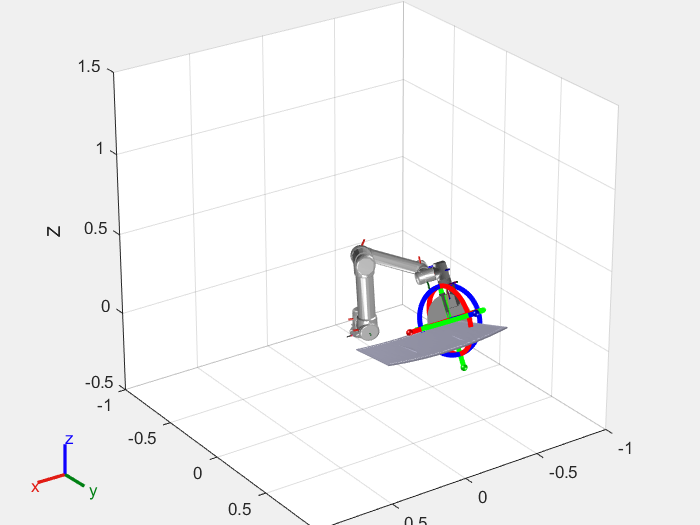

zoom reset;
pan off;
view(145,25);

set(gcf,'KeyPressFcn',{@exampleHelperSetOrientations,selectedWaypoints,ur5_iRBT,ik});
disp("Press Up-Down arrow key to rotate about the X-axis. Press Left-Right arrow key to rotate about the Y-axis.");

Press Up-Down arrow key to rotate about the X-axis. Press Left-Right arrow key to rotate about the Y-axis.


disp("Press C to save orientation for current waypoint and press N to move to the next waypoint.");

Press C to save orientation for current waypoint and press N to move to the next waypoint.


### Set Orientation of Each Desired Waypoint

Adjust the orientation for the desired waypoints using the keyboard keys. Here are the details of the attached keyboard keys callback. Before using this keyboard button, ensure that no figure window tool is selected.

- Up Arrow / Down Arrow: To change the orientation of the cobot end-effector tool about X-direction

- Right Arrow / Left Arrow: To change the orientation of the cobot end-effector tool about Y-direction

- C: To save the orientation data for the current waypoint

- N: To move to the next waypoint from the current waypoint

If you want to skip the current waypoint and do not want to consider it in the trajectory computation, then just press the 'N' button without saving the orientation data. 

**Note:  Use interactive marker only for the rotational adjustment of the end-effector.**

To use an interactive marker for setting the orientation, you can click and rotate the body about an axis using the red, green, and blue circles. To disable the marker body. right-click on the tool body and click "Toggle marker on/off". It is advisable to use the marker for major corrections and keyboard keys for finer adjustments.

**Note:  If you want to consider default orientations for further sections, then you can run this section without setting orientation.**

### Get the Final Waypoint and Orientation Data

Get the desired orientation data for the motion planning. If orientation is not set for the desired waypoints, then it used the default orientation as mentioned in this code section. This section also removes the 'KeyPressFcn' callback. 

% remove the keyboard callback
set(gcf,'KeyPressFcn',[]);

% Move cobot to the home position
ur5_iRBT.Configuration = q_home;

% Disable the marker from the tool body
ur5_iRBT.ShowMarker = false;


% Get the desired waypoint and orientation data
[finalWaypoints, finalOrientations]= exampleHelperGetFinalWaypointData();

% Consider the default waypoint and orientation data if no orientation
% setting has been done for waypoints
if isempty(finalOrientations) && isempty(finalWaypoints)
    finalWaypoints = selectedWaypoints;
    finalOrientations = repmat([0 0 -pi/3],size(finalWaypoints,1),1);
end

### Task Space Trajectory Planning Algorithm (Based on Inverse Kinematics)

The task space trajectory planning algorithm used in this example takes the input argument as user-defined TCP velocity and the time resolutions for the trajectory computation. These are the high-level steps implemented to generate the desired trajectory.

- Get the desired waypoints and orientation array with the desired TCP velocity and time resolution.

- Consider the path segment between two consecutive waypoints.

- Find the distance of the path segment.

- Find the time to traverse for the considered path segment from the distance calculated and the input TCP velocity.

- Get intermediate waypoint transforms using [`transformtraj`](https://www.mathworks.com/help/robotics/ref/transformtraj.html) using computed trajectory time array, considering the time resolution that you defined.

- Compute the joint data using [`inverseKinematics`](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html) at each intermediate waypoint.

- Compute the joint velocity and acceleration using [`minjerkpolytra`j](https://www.mathworks.com/help/robotics/ref/minjerkpolytraj.html).

For more details, refer to the helper function `exampleHelperURGenerateTrajectory `attached with this example.

### Compute the Trajectory to Traverse Through the Desired Waypoints on the Windshield

Compute the second trajectory for traversing through the desired waypoints on the windshield. 

% Desired tool center point (TCP) velocity
velOfTCPForTask = 0.15;

% Desire time step resolution
dtForTask = 0.02;

computedTrajForTask = exampleHelperURGenerateTrajectory(ur5_RBT,config',finalWaypoints,finalOrientations,velOfTCPForTask,dtForTask);
trajTimes = 0:dtForTask:(size(computedTrajForTask.position,1)-1)*dtForTask;

### Move Cobot Near to the Windshield at the First Selected Desired Waypoint

Compute the first trajectory which moves the cobot from the home position to the first selected desired waypoint. 

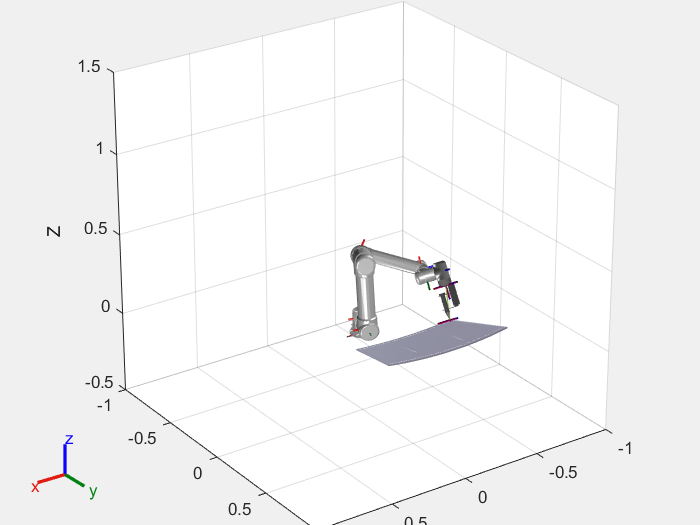

% Move cobot to the first desired waypoint
ur5_iRBT.Configuration = computedTrajForTask.position(1,:);

### Rigid Body Tree Simulation of the Computed Trajectory

Visualize the computed trajectory using Rigid Body Tree simulation.

% TCP position in cartesian coordinates
posTCPForTask = computedTrajForTask.posTCP;

r = rateControl(1/dtForTask); % Rate to control the for loop execution
for idx = 1:size(computedTrajForTask.position,1)
    config = computedTrajForTask.position(idx,:);
    ur5_iRBT.Configuration = config';
    plot3(posTCPForTask(idx,1),posTCPForTask(idx,2),posTCPForTask(idx,3),'color','b','Marker','.','MarkerSize',5)
    waitfor(r);
end


### Plot the Joint Position, Joint Velocity, Joint Acceleration, and TCP Linear Velocity of Computed Trajectory

eeSpeed = zeros(length(computedTrajForTask.position),6);
for i=1:length(computedTrajForTask.position)
    % Calculate geometric jacobian
    jacobian = geometricJacobian(ur5_RBT,computedTrajForTask.position(i,:),'dispenserEdge');

    % Calculate end-effector velocity
    eeSpeed(i,:) = (jacobian*computedTrajForTask.velocities(i,:)')';
end

close(findobj('type','figure','name','Desired joint position'));
hFig1 = figure('Name','Desired joint position');
set(hFig1,'Visible','on')
sgtitle("Desired joint position")
for i=1:6    
    subplot(2,3,i);   
    plot(trajTimes,computedTrajForTask.position(:,i));
    titleString = "Actuator:" + num2str (i);
    title(titleString);
    ylabel("Angle(rad)");
    xlabel("Time(second)");
    grid on;
    axis auto;
end

close(findobj('type','figure','name','Desired joint velocity'));
hFig2 = figure('Name','Desired joint velocity');
set(hFig2,'Visible','on')
sgtitle("Desired joint velocity")
for i=1:6   
    subplot(2,3,i);
    plot(trajTimes,computedTrajForTask.velocities(:,i));
    titleString = "Actuator:" + num2str (i);
    title(titleString);
    ylabel("Velocity(rad/s)");
    xlabel("Time(second)");
    grid on;
    axis auto;
end

close(findobj('type','figure','name','Desired joint acceleration'));
hFig3 = figure('Name','Desired joint acceleration');
set(hFig3,'Visible','on')
sgtitle("Desired joint acceleration")
for i=1:6   
    subplot(2,3,i);
    plot(trajTimes,computedTrajForTask.acceleration(:,i));
    titleString = "Actuator:" + num2str (i);
    title(titleString);
    ylabel("Acceleration(rad/s^2)");
    xlabel("Time(second)");
    grid on;
    axis auto;
end

close(findobj('type','figure','name','Desired end-effector linear velocity'));
hFig4 = figure('Name','Desired end-effector linear velocity');
set(hFig4,'Visible','on')
plot(trajTimes,vecnorm(eeSpeed(:,4:6)'));
title("Desired end-effector linear velocity")
ylabel("Velocity(m/s)");
xlabel("Time(second)");
grid on;
axis auto;

## ROS-Gazebo Simulation

Gazebo simulation uses the ROS interface and `urROSNode` object to control the simulated robot in Gazebo. The `urROSNode` object uses a motion planning algorithm offered by Robotics System Toolbox to achieve joint space control, task space control, waypoint tracking in task space, and waypoint tracking in joint space. 

Press ‘y’ and press 'Enter' key on the keyboard in the MATLAB command window to continue with the Gazebo simulation or press 'n' to return. The Gazebo simulation requires the setup. Refer to [Install ROS Packages and Dependencies for ROS](docid:robotmanipulator_ug#mw_313af52d-db69-4e68-809e-09dfa1fb9273) for more details.

prompt = 'Do you want to simulate the trajectory in Gazebo? (y/n) [n]';
str = input(prompt,'s');

if isempty(str)
    str = 'n';
end
 
if str == 'n'
    return;
end

### Connect to ROS Device and Launch Gazebo Model

Modify the below ROS device parameters as per your system before running this section. 

%% ROS device parameters
ROSDeviceAddress = '172.21.168.123';
username = 'user';
password = 'Constantin2276';
ROSFolder = '\\wsl.localhost\Ubuntu\opt\ros\jazzy';
WorkSpaceFolder = '~/ur_ws';

Connect to ROS device.

device = rosdevice(ROSDeviceAddress,username,password);

Error using ros.codertarget.internal.ssh2client (line 48)
Error connecting to SSH server at 172.21.168.123

Error in ros.codertarget.internal.RemoteLnxSystemExecutor (line 20)
            obj.Ssh = ros.coder

device.ROSFolder = ROSFolder;

###  Copy Required Files to ROS Machine and Build the catkin Workspace

% Check if the custom folder present
response = system(device,['cd ' WorkSpaceFolder '/src; ls']);
if ~contains(response,'ur_glue_dispensing_gazebo')
    % Copy file into ROS device
    putFile(device,fullfile('ur_glue_dispensing_gazebo.zip'),[WorkSpaceFolder '/src']);

    % Unzip
    system(device,['unzip ' WorkSpaceFolder '/src/ur_glue_dispensing_gazebo.zip' ' -d ' WorkSpaceFolder '/src/']);

    % Delete Zip
    system(device,['rm ' WorkSpaceFolder '/src/ur_glue_dispensing_gazebo.zip']);

    % Find and replace workspace name in world file
    system(device,['cd ' WorkSpaceFolder '/src/ur_glue_dispensing_gazebo/worlds;' ' sed -i s/ur_ws/' extractAfter(WorkSpaceFolder,'/') ...
        '/g ur_glue_dispensing_gazebo.world']);

    % Catkin_make
    system(device,['cd ' WorkSpaceFolder ';' ' source ' ROSFolder '/setup.bash;' ...
        ' catkin_make --only-pkg-with-deps ur_glue_dispensing_gazebo;' 'source devel/setup.bash']);
end

### Generate Launch Script and Copy It to Host Machine

generateAndTransferLaunchScriptGlueDispensing(device,WorkSpaceFolder);

###  Launch the Gazebo World with Required ROS Nodes

if ~isCoreRunning(device)
    w = strsplit(system(device,'who'));
    displayNum = cell2mat(w(2));

    system(device,['export SVGA_VGPU10=0; ' ...
        'export DISPLAY=' displayNum '.0; ' ...
        './launchURGlueDispensing.sh &']);
end

### **Initialize the urROSNode Interface**

Create `urROSNode` object to communicate with Universal Robot's Gazebo model.

ur = urROSNode(ROSDeviceAddress,'RigidBodyTree',ur5_RBT);

### Command Cobot to Move to the First Selected Desired Waypoint from Home Position

Command the cobot to move the first selected waypoint using `sendJointConfiguration `method`.`

sendJointConfiguration(ur,computedTrajForTask.position(1,:),'EndTime',4);

### Send the Computed Trajectory of the Glue Dispensing Application

Send the computed trajectory to traverse the cobot through the desired waypoints over the windshield body. 

Use the previously computed time vector.

Send the followTrajectory command to the cobot's Gazebo model.

 followTrajectory(ur,computedTrajForTask.position',computedTrajForTask.velocities',computedTrajForTask.acceleration',trajTimes);

Kill the rosmaster and gazebo.

clear ur;
system(device,'killall -9 rosmaster');

*Copyright 2022 The MathWorks, Inc.*